% Test Zone

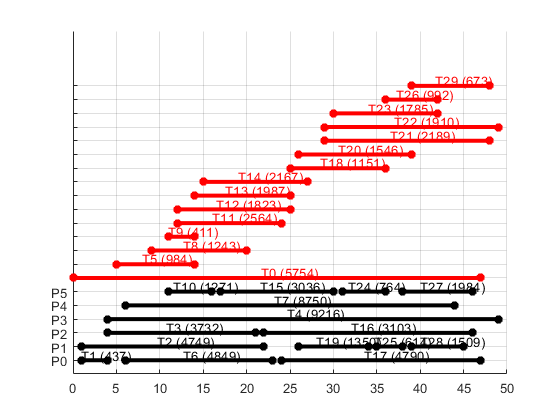

% Tabela de tasks

clear all
str = convertStringsToChars(splitlines(extractFileText('tasks_30_06_0.txt')));
profits = str2double(splitlines(extractFileText('profits_30_06_0.txt')));
progs={};
prog={};
tasks={};
for p=1:(length(str)-1)
    if(str{p}(1)=='P')
        progs{p} = split(str(p));
        final = p;
    else
        tasks{(p-(final))}=split(str(p));
    end
end
margem = p*2/100;

figure(1)

%prints
close all
hold on
for  i= 1:final
    for k=3:3:(length(progs{i})-1)
        t=(str2double(progs{i}{k-1}):str2double(progs{i}{k+1}));
        p=ones(1,length(t));
        title = progs{i}{k};
        fim = length(regexp(title,'[0-9]'))+1;
        if fim ==2
            iprofit = str2num(title(2))+1;
        else
            iprofit = str2num(title(2:fim))+1;
        end
        if(profits(iprofit)~=1)
            txt = [progs{i}{k},' (',int2str(profits(iprofit)),')'];
            avg =(t(1)+(t(end)-t(1))/2)-length(txt)/5;
        else
            txt = title;
            avg =(t(1)+(t(end)-t(1))/2)-0.3;
        end
        text(avg,i+margem,txt,'Color','k');
        prog{i} = char(progs{i}(1));
        plot(t, i*p, 'k-',"LineWidth",3);
        plot(t(1),i*p, 'k*',"LineWidth",3);
        plot(t(end),i*p, 'k*',"LineWidth",3)
    end   
end

for q=1:length(tasks)
    t=(str2double(tasks{q}{1}):str2double(tasks{q}{3}));
    p=ones(1,length(t));
    title = tasks{q}{2};
    fim = length(regexp(title,'[0-9]'))+1;
    iprofit = str2num(title(2:fim))+1;
    if(profits(iprofit)~=1)
        txt = [tasks{q}{2},' (',int2str(profits(iprofit)),')'];
        avg =(t(1)+(t(end)-t(1))/2)-length(txt)/5;
    else
        txt = title;
        avg =(t(1)+(t(end)-t(1))/2)-0.3;
    end
    text(avg,((q+final)+margem),txt,'Color','r');
    plot(t, (q+final)*p, 'r-',"LineWidth",3);
    plot(t(1),(q+final)*p, 'r*',"LineWidth",3);
    plot(t(end),(q+final)*p, 'r*',"LineWidth",3)
    prog{q+final} = char('');
end
hold off
grid;
ay = gca;
ay.YTickLabel = prog;
yticks(1:length(prog));

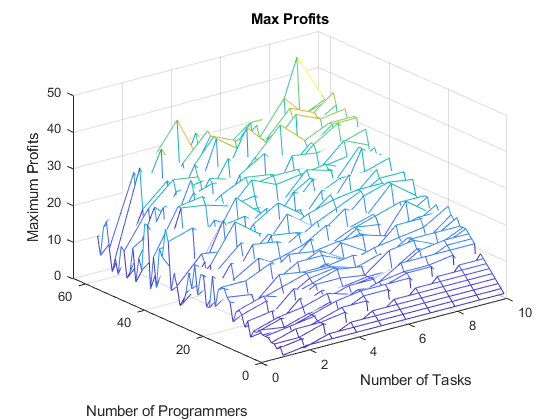

% Results profits

clear all
results = load('profitfilename1.txt');
tasks=results(:,1);
progs=results(:,2);
profit=results(:,3);
profits= zeros(64,10);
for i=1:length(profit)
        profits(tasks(i),progs(i))=profit(i);
end
mesh(profits);
title("Max Profits")
xlabel("Number of Tasks");
ylabel("Number of Programmers");
zlabel("Maximum Profits");

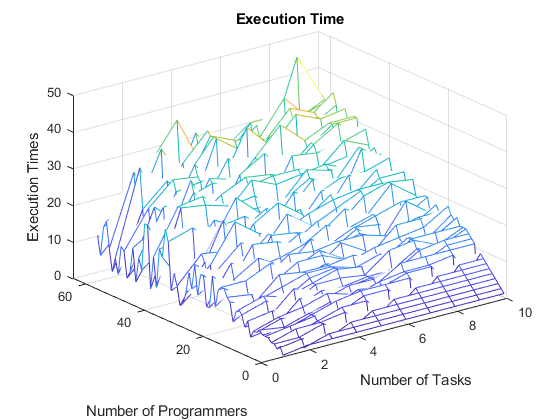

% Results time

clear all
results = load('profitfilename1.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=time(i);
end
mesh(times);
title("Execution Time")
xlabel("Number of Tasks");
ylabel("Number of Programmers");
zlabel("Execution Times");